clearvars; close all; % clear variables in workspace and close all figures


% reading the data
data = readtimetable('../Datasets/Saint John/SaintJohnEnergy.xlsx');

% TR = timerange('2010-01-01','2019-12-31 23:00:00', "closed");
% data = data(TR, :);   % new total dataset

% detecting and removing outliers using Hampel filter
data.DemandMW = hampel(data.DemandMW);
data.Temperature = hampel(data.Temperature);
data.Humidity = hampel(data.Humidity);
data.Dewpoint = hampel(data.Dewpoint);
data.WindDirection = hampel(data.WindDirection);
data.WindSpeed = hampel(data.WindSpeed);

% Normalizing the variables % y = (x - min) / (max - min)

tmp = timetable2table(data);
maxdp = max(table2array(tmp(:, 2:end)));    % takes the max and min of each variable in the dataset
mindp = min(table2array(tmp(:, 2:end)));
tmp.DateTime = [];
normalize = (table2array(tmp) - mindp) ./ (maxdp - mindp);

% creating the normalized dataset
ndata = data;
ndata.DemandMW = normalize(:, 1);
ndata.Temperature = normalize(:, 2);
ndata.Humidity = normalize(:, 3);
ndata.Dewpoint = normalize(:, 4);
ndata.WindDirection = normalize(:, 5);
ndata.WindSpeed = normalize(:, 6);

% norm / denormalization function 
norm = @(x, Max, Min)((x-Min)/(Max-Min)); % y = (x - min) / (max - min)
denorm = @(y,Max,Min)(y*(Max-Min)+Min);
Min =mindp(1); Max= maxdp(1);

% clearvars -except data ndata mindp maxdp

% Training and Testing Data Split
TR = timerange('2018-01-01','2020-10-20 23:00:00', "closed");
trainvald = ndata(TR, :);   % training data

TR = timerange('2020-10-21','2021-10-20 23:00:00', "closed");
testd = ndata(TR, :);   % testing data 

## Training the Forecasters

### Inputs and Targets Creation

[inputs, blf_outputs, clf_outputs, time_outputs, p] = InputsCreation(trainvald);

### Base Load Forecaster training

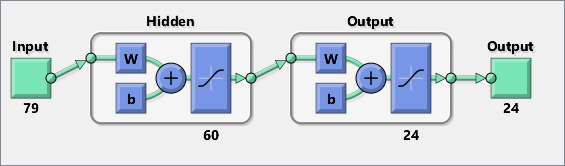

clear net

x = inputs;
t = blf_outputs;

% trainFcn = 'trainlm';  % Levenberg-Marquardt backpropagation. Was quite slow in training
trainFcn = 'trainrp';   % Resilient backpropagation. Good for pattern recognition problems


% Create a Fitting Network
hiddenLayerSize = 60;   % 30 - 60 neurons
% net = feedforwardnet(hiddenLayerSize,trainFcn);
net = fitnet(hiddenLayerSize,trainFcn);

% logsig = 1 / 1 + e^(-z) ; tansig = 2/(1+exp(-2*n))-1;
% using tansig gave better predictions.
% Increasing the no. of neurons didn't make logsig prediction better.
net.layers{1}.transferFcn = 'tansig'; % converts the output layer's function to sigmoid
net.layers{2}.transferFcn = 'tansig'; % converts the output layer's function to sigmoid


% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 80/100;
net.divideParam.valRatio = 20/100;
net.divideParam.testRatio = 0/100;
% net.divideFcn = 'divideblock';


% Train the Network
[net,trBLF] = train(net,x,t);

% % Getting the datasets used in training, validation, and testing
% train_set = blf_outputs(:,trBLF.trainInd);
% val_set = blf_outputs(:,trBLF.valInd);
% test_set = blf_outputs(:,trBLF.testInd);

% Test the Network
% y = net(x);
% e = gsubtract(t,y);
% performance = perform(net,t,y)

% View the Network
newView(net)

blf_net = net;

### Change in the Load Forecaster Training

clear net

x = inputs;
t = clf_outputs;

% trainFcn = 'trainlm';  % Levenberg-Marquardt backpropagation. Was quite slow in training
trainFcn = 'trainrp';   % Resilient backpropagation


% Create a Fitting Network
hiddenLayerSize = 60;   % 30 - 60 neurons
% net = feedforwardnet(hiddenLayerSize,trainFcn);
net = fitnet(hiddenLayerSize,trainFcn);

% logsig = 1 / 1 + e^(-z) ; tansig = 2/(1+exp(-2*n))-1;
% using tansig gave better predictions.
% Increasing the no. of neurons didn't make logsig prediction better.
net.layers{1}.transferFcn = 'tansig'; % converts the output layer's function to sigmoid
net.layers{2}.transferFcn = 'tansig'; % converts the output layer's function to sigmoid


% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 80/100;
net.divideParam.valRatio = 20/100;
net.divideParam.testRatio = 0/100;
% net.divideFcn = 'divideblock';

% Train the Network
[net,trCLF] = train(net,x,t);

% % Getting the datasets used in training, validation, and testing
% train_set = clf_outputs(:,trCLF.trainInd);
% val_set = clf_outputs(:,trCLF.valInd);
% test_set = clf_outputs(:,trCLF.testInd);

% Test the Network
% y = net(x);
% e = gsubtract(t,y);
% performance = perform(net,t,y)

% View the Network
newView(net)
clf_net = net;

## Predict the test dataset

% Generating the inputs for the entire dataset
[inputs, blf_outputs, clf_outputs, time_outputs, p] = InputsCreation(testd);

### Generate BLF forecasts

% generate the forecasts
raw_blf = blf_net(inputs);

% denormalize predicted values
yBLF = raw_blf * (maxdp(1) - mindp(1)) + mindp(1);

% these are the actual, denormalized load demand values 
actuals = blf_outputs * (maxdp(1) - mindp(1)) + mindp(1);

### Generate CLF forecasts

% generate the forecasts
raw_clf = clf_net(inputs) + p(:,1:end-1);

% denormalize predicted values
yCLF = raw_clf * (maxdp(1) - mindp(1)) + mindp(1);

### Generate RLS forecasts

days = size(yBLF);
days = days(2);

% calls the rls combiner function
[yRLS, w] = RLS_Combiner(raw_blf, raw_clf, blf_outputs, days); % uses normalized values as inputs

% denormalize the rls combination
yRLS = yRLS*(maxdp(1) - mindp(1)) + mindp(1);

### Calculate errors

[Metrics,eBLF, blf_AEs, blf_APEs, eCLF, clf_AEs, clf_APEs,...
eRLS, rls_AEs, rls_APEs, blf_MAPE, clf_MAPE, rls_MAPE] = ErrorMetrics(actuals, yBLF, yCLF, yRLS);

Metrics

### Plots of the Test dataset

figure;

% plot actual values
plot(time_outputs, actuals(:), 'DisplayName','Actual Values')
title('BLF, CLF and RLS forecasts')
ylabel('Load demand (MW)')
grid on; 
hold on;

% plot blf forecast
DisplayName = num2str(blf_MAPE, 'BLF Forecast (MAPE = %.2f%%)');
plot(time_outputs,yBLF(:), 'DisplayName', DisplayName)

% plot clf forecast
DisplayName = num2str(clf_MAPE, 'CLF Forecast (MAPE = %.2f%%)');
plot(time_outputs,yCLF(:), 'DisplayName', DisplayName)

% plot rls forecast
DisplayName = num2str(rls_MAPE, 'RLS Forecast (MAPE = %.2f%%)');
plot(time_outputs,yRLS(:), 'DisplayName', DisplayName)
legend('show')

## Peak Detection

[DailyPeak]= PeakDetection(time_outputs, actuals, yRLS);
DailyPeak
% Overall MAPE
DayPk_MAPE = mean(DailyPeak.APEs)
% gives you the hours, minutes, seconds
DayPk_TimeDiff_MBE = round(minutes(hours(mean(DailyPeak.TimeDiff)))) 
DayPk_TimeDiff_MAE = round(minutes(hours(mean(abs(DailyPeak.TimeDiff)))))  

% Plots of the daily peaks
figure;
plot(DailyPeak.Time, DailyPeak.ActPk, 'DisplayName','Actual')
title('Daily Peaks')
hold on
plot(DailyPeak.Time, DailyPeak.PredPk, 'DisplayName', 'Predicted')
grid on
legend('show')